# Script for calculating different second order motifs

Brief description: This livescript imports the cell table (tcell) and the connection table (tconnection) and calculated the occcurence of different second order motifs. One can choose which cell types should be included at which position in the motif. Further the occurence of these motifs are compared to randomly generated networks which assume the overall subtype-specific connection probabilities.

Import excel tables and calculate degrees

n_celltypes = 2;    %choose PC/IN if IN are supposed to be pooled. Choose PC/FS/NFS if IN subtypes are to be analysed
layer = 0;          %choose layer. Publication mostly focused on superficial layer

central_celltype = 1;
partner_celltype = 0;

%these excel files need to be in the source folder
tcell = readtable('\tcell.xlsx');
tcell = sortrows(tcell,'IDcell','ascend');
    
tconnection = readtable('\tconnection.xlsx');
tconnection.IDpre = string(tconnection.IDpre);
tconnection.IDpost = string(tconnection.IDpost);
tconnection = tconnection(tconnection.synaptic_layer == layer,:); %remove cells without coordinates

if n_celltypes == 2
    tconnection.stype = tconnection.Synaptic_Type_PCIN;
    tcell.ctype = tcell.cell_type_PC_IN;
elseif n_celltypes == 3
    tconnection.stype = tconnection.Synaptic_Type;
    tcell.ctype = tcell.cell_type_3;
end

for i = 1:size(tcell,1)
    pre = tconnection.IDpre == tcell.IDcell{i};
    post = tconnection.IDpost == tcell.IDcell{i};
    
    for s = 1:max(tconnection.stype)
        stype = tconnection.stype == s;
        tcell.in_found(i,s) = sum(tconnection.Connected(post & stype));
        tcell.in_tested(i,s) = numel(tconnection.Connected(post & stype));
        tcell.out_found(i,s) = sum(tconnection.Connected(pre & stype));
        tcell.out_tested(i,s) = numel(tconnection.Connected(pre & stype));
        tcell.in_recfound(i,s) = sum(tconnection.reciprocity(post & stype));
        tcell.out_recfound(i,s) = sum(tconnection.reciprocity(pre & stype));
    end
end

Connection type numbering correspond to either

PC-PC, PC-IN, IN-PC, IN-IN   -or-   PC-PC, PC-FS, PC-NFS, FS-PC, FS-FS, FS-NFS, NFS-PC, NFS-FS, NFS-NFS

if n_celltypes == 2
    synapse_matrix = [1 2; 3 4];
elseif n_celltypes == 3
    synapse_matrix = [1 2 3; 4 5 6; 7 8 9];
end
fil = tcell.ctype == central_celltype;
out_s = synapse_matrix(central_celltype+1,partner_celltype+1);
in_s = synapse_matrix(partner_celltype+1,central_celltype+1);

Calculate chain and doublerec motifs for each cell and calculate clusterwise aggregate of motifs

n_cell = numel(tcell.ctype(fil))

n_cell = 251

out_found = sum(tcell.out_found(fil,out_s))

out_found = 100

out_tested = sum(tcell.out_tested(fil,out_s))

out_tested = 506

out_prob = out_found/out_tested

out_prob = 0.1976


in_found = sum(tcell.in_found(fil,in_s))

in_found = 101

in_tested = sum(tcell.in_tested(fil,in_s))

in_tested = 506

in_prob = in_found/in_tested

in_prob = 0.1996


%calculate 2nd order motif for each cell
tcell.in_prob = tcell.in_found ./ tcell.in_tested;
tcell.out_prob = tcell.out_found ./ tcell.out_tested;

tcell.divergent_found = tcell.out_found .* (tcell.out_found-1) ./2;
tcell.divergent_tested = tcell.out_tested .* (tcell.out_tested-1) ./2;

tcell.convergent_found = tcell.in_found .* (tcell.in_found-1) ./2;
tcell.convergent_tested = tcell.in_tested .* (tcell.in_tested-1) ./2;

tcell.chain_found = tcell.in_found(:,in_s) .* tcell.out_found(:,out_s) - tcell.out_recfound(:,out_s);
tcell.doublerec_found(tcell.out_recfound(:,out_s) >= 2) = tcell.out_recfound(tcell.out_recfound(:,out_s) >= 2,out_s) .* (tcell.out_recfound(tcell.out_recfound(:,out_s) >= 2,out_s)-1) ./ 2;

%subset tconnection
confil = tconnection.stype == out_s;
tconnection2 = tconnection(confil,:);

% create tcluster, only include cells with xy coordinates
tcluster = table();
tcluster.id = categorical(unique(tconnection2.Idslice));
for i = 1:size(tcluster,1)
    cell_central_filter = tcell.Idslice == tcluster.id(i) & tcell.ctype == central_celltype & tcell.layer_sup_deep == layer & ~isnan(tcell.coordinateX);
    cell_partner_filter = tcell.Idslice == tcluster.id(i) & tcell.ctype == partner_celltype & tcell.layer_sup_deep == layer & ~isnan(tcell.coordinateX);
    tcluster.n_central(i) = sum(cell_central_filter);
    tcluster.n_partner(i) = sum(cell_partner_filter);
    tcluster.rec_found(i) = sum(tcell.out_recfound(cell_central_filter,out_s));
    tcluster.doublerec_found(i) = sum(tcell.doublerec_found(cell_central_filter));
    tcluster.out_found(i) = sum(tcell.out_found(cell_central_filter,out_s));
    tcluster.in_found(i) = sum(tcell.in_found(cell_central_filter,in_s));
    tcluster.div_found(i) = sum(tcell.divergent_found(cell_central_filter,out_s));
    tcluster.con_found(i) = sum(tcell.convergent_found(cell_central_filter,in_s));
    tcluster.chain_found(i) = sum(tcell.chain_found(cell_central_filter));
end
 
rec_found = sum(tcluster.rec_found)

rec_found = 39

con_found = sum(tcluster.con_found)

con_found = 59

div_found = sum(tcluster.div_found)

div_found = 59

chain_found = sum(tcluster.chain_found)

chain_found = 87

doublerec_found = sum(tcluster.doublerec_found)

doublerec_found = 15

**Simulate random networks with distance dependence**

Calculate distance-dependence of connectivity

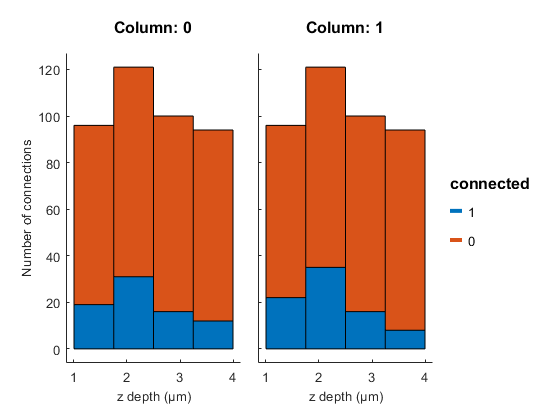

confil = tconnection.synaptic_layer == layer & ~isnan(tconnection.Distance);
tconnection_xy = tconnection(confil,:);
if n_celltypes == 2
    subset = tconnection_xy.stype == 2 |tconnection_xy.stype == 3;
    column = tconnection_xy.stype == 2;
elseif n_celltypes == 3
    subset = tconnection_xy.stype == 2 |tconnection_xy.stype == 3 |tconnection_xy.stype == 4 |tconnection_xy.stype == 7;
    column = tconnection_xy.stype == 2 |tconnection_xy.stype == 3;
end

bins = [0 50 75 100 300];
dist_bin = discretize(tconnection_xy.Distance,bins);

%number of found/tested connection
figure
g = gramm('x',dist_bin,'color',tconnection_xy.Connected,'subset',subset,'column',column);
g.stat_bin('geom','stacked_bar','nbins',4);
g.set_color_options('map','matlab');
g.set_order_options('color',-1);
g.set_names('x','z depth (µm)','y','Number of connections','color','connected');
g.draw;

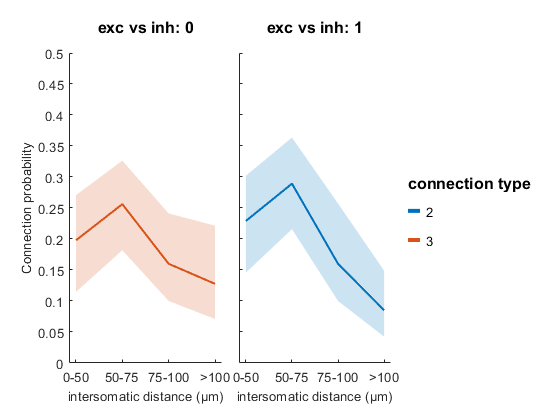


%connection probability
figure
g = gramm('x',dist_bin,'y',tconnection_xy.Connected','color',tconnection_xy.stype,'subset',subset,'column',column);
g.stat_summary('type','bootci');
g.axe_property('YLim',[0 0.5]);
g.set_names('x','intersomatic distance (µm)','y','Connection probability','color','connection type','column','exc vs inh');
g.set_color_options('map','matlab');
g.axe_property('XTickLabel',{'0-50','50-75','75-100','>100'},'XTick',[1:length(bins)-1]);
g.draw();

Get distance-dependent connectivity and bins. Only include connections with xy coordinates of cells

confil = (tconnection.stype == in_s | tconnection.stype == out_s) & tconnection.synaptic_layer == layer & ~isnan(tconnection.Distance);
tconnection_xy = tconnection(confil,:);

bins = [0 50 75 100 300];
tconnection_xy.dist_group = discretize(tconnection_xy.Distance,bins);

tdist = groupsummary(tconnection_xy,{'dist_group','stype'},{'sum','mean'},'Connected');
dist_out_prob = tdist.mean_Connected(tdist.stype == out_s);
dist_in_prob = tdist.mean_Connected(tdist.stype == in_s);

Simulate random count of motifs from 10,000 random simulations

repeats = 10000;
[erdist_div_found,erdist_con_found,erdist_chain_found,erdist_rec_found,erdist_doublerec_found] =  secondorder_er_distance(tcluster,tcell,bins,dist_out_prob,dist_in_prob,repeats,central_celltype,partner_celltype,layer);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Calculates mean and std of random simulations.

Calculates rank-based p-value for comparison (see methods).

figure
random_rec = nansum(erdist_rec_found,[2 3]);
histogram(random_rec);
random_rec_mean = mean(random_rec)

random_rec_mean = 17.6333

random_rec_std = std(random_rec)

random_rec_std = 4.0364

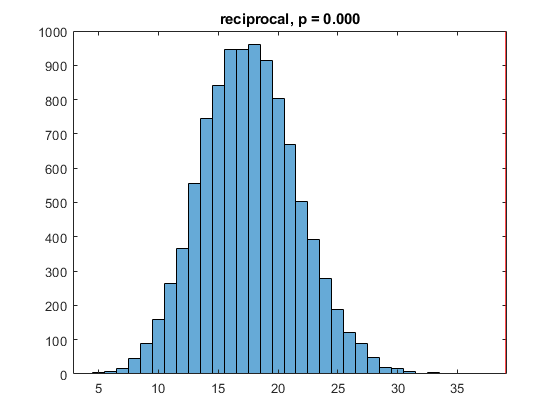

xline(rec_found,'r',rec_found);
p_rank = max(sum(random_rec>rec_found),1/numel(random_rec))/numel(random_rec);
title(sprintf('reciprocal, p = %.3f',p_rank));


figure
random_con = nansum(erdist_con_found,[2 3]);
histogram(random_con);
random_con_mean = mean(random_con)

random_con_mean = 27.2928

random_con_std = std(random_con)

random_con_std = 7.0593

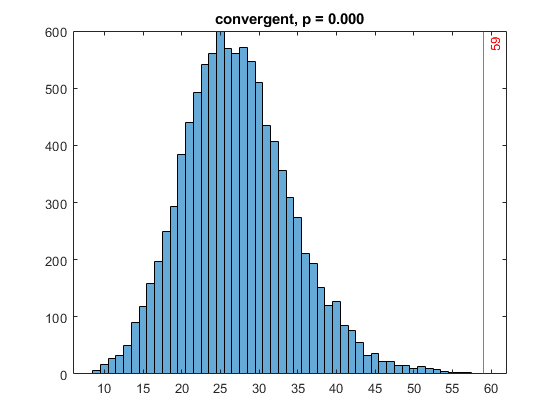

xline(con_found,'r',con_found)
p_rank = max(sum(random_con>con_found),1/numel(random_con))/numel(random_con);
title(sprintf('convergent, p = %.3f',p_rank));


figure
random_div = nansum(erdist_div_found,[2 3]);
histogram(random_div);
random_div_mean = mean(random_div)

random_div_mean = 24.7246

random_div_std = std(random_div)

random_div_std = 6.7033

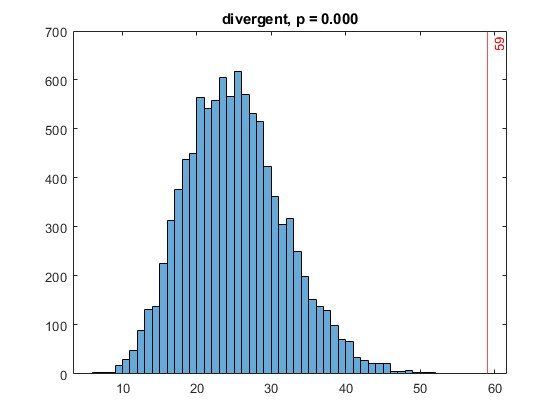

xline(div_found,'r',div_found)
p_rank = max(sum(random_div>div_found),1/numel(random_div))/numel(random_div);
title(sprintf('divergent, p = %.3f',p_rank));


figure
random_chain = nansum(erdist_chain_found,[2 3]);
histogram(random_chain)
random_chain_mean = mean(random_chain)

random_chain_mean = 51.8352

random_chain_std = std(random_chain)

random_chain_std = 9.8006

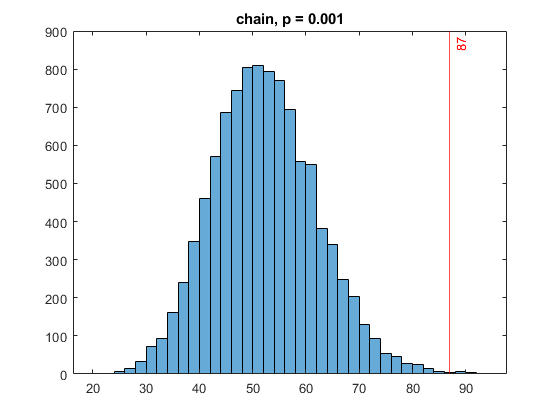

xline(chain_found,'r',chain_found)
p_rank = max(sum(random_chain>chain_found),1/numel(random_chain))/numel(random_chain);
title(sprintf('chain, p = %.3f',p_rank));


figure
random_doublerec = nansum(erdist_doublerec_found,[2 3]);
random_doublerec_mean = mean(random_doublerec)

random_doublerec_mean = 2.8944

random_doublerec_std = std(random_doublerec)

random_doublerec_std = 3.2182

p_rank = max(sum(random_doublerec>doublerec_found),1/numel(random_doublerec))/numel(random_doublerec);

Plot Fig 1E: random distribution as box plot and normalized overrepresentation of data count to mean random count

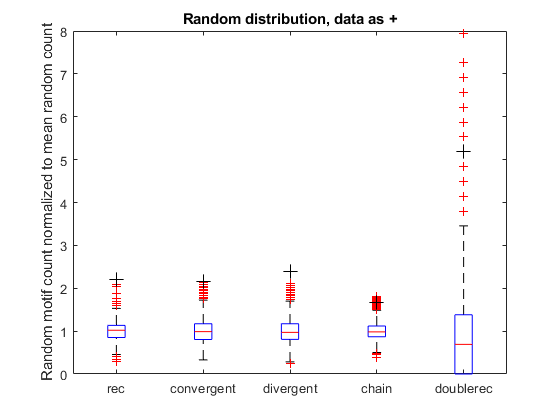

found_motif = [rec_found con_found div_found chain_found doublerec_found];
random_motif = [random_rec_mean random_con_mean random_div_mean random_chain_mean random_doublerec_mean];
random_motif_std = [random_rec_std random_con_std random_div_std random_chain_std random_doublerec_std];

labels = {'rec','convergent','divergent','chain','doublerec'};

random_motif_count = [random_rec random_con random_div random_chain random_doublerec];
random_motif_norm = random_motif_count ./ mean(random_motif_count);
data_motif_count = [rec_found con_found div_found chain_found doublerec_found];
data_motif_norm = data_motif_count ./ random_motif;

figure
boxplot(random_motif_norm,'Widths',0.2)
hold on
plot(data_motif_norm,'+','MarkerSize',10,'MarkerEdgeColor','black')
hold off
ylim([0 8]);
xticklabels(labels)
ylabel('Random motif count normalized to mean random count')
title('Random distribution, data as +')